# Kalman Filter Design

% This example shows how to perform Kalman filtering. 

% Based on one example from The MathWorks, Inc., Copyright 1986-2012 .

clc
clear
close all

## Time-Varying Kalman Filter Design

% Now, design a time-varying Kalman filter to perform the same task. A time-varying 
% Kalman filter can perform well even when the noise covariance is not stationary. 
% However for this example, we will use stationary covariance.
% 
% The time varying Kalman filter has the following update equations.

## Problem Description

Given the following discrete plant


$$ x(n+1) = Ax(n) + Bu(n) + Bw(n) $$



$$ y(n) = Cx(n) + Du(n) $$


where

F = [1.1269   -0.4940    0.1129;
    1.0000         0         0;
    0    1.0000         0;];

B = [-0.3832
    0.5919
    0.5191];

C = [1 0 0];

D = 0;

A = F; % The problem provides the digitalized process matrix

Design a Kalman filter to estimate the output y based on the noisy measurements yv[n] = C x[n] + v[n]

## Noises specification

% Specify the process noise covariance (Q), or how much dod you trust the model?
[n, p] = size(B);
Q = 0.1 * eye(p); % A number greater than zero

% Specify the sensor noise covariance (R), or how much dod you trust the 
% output sensor?

[m, ~] = size(C);
R = 2 * eye(m); % A number greater than zero

## Generate a sinusoidal input vector (known):

dt = 1;
t = (0:dt:100)';
u = sin(t/5);

## First, generate the noisy state sequence:

N = length (t);

P_0 = 10 * diag(ones(n,1));  % Initial (prior) error covariance
x_0 = zeros(n,1);            % Initial (prior) condition on the state

% Preallocate
X  = zeros(n, N);
Xn = zeros(n, N);

% Process noise sequence
MU = zeros (N+1, p);
v = mvnrnd (MU, Q);

% Propagate prior information
Xn(:, 1) =  mvnrnd(x_0, P_0)';
X(:, 1)  =  mvnrnd(x_0, P_0)';

for i = 2:N
    
    Xn(:, i) = A * Xn(:, i-1) + B * u(i) + (v(i,:))';
    X (:, i) = A * X (:, i-1) + B * u(i);
end

## Then, generate the noisy plant response:

% Preallocate
Y  = zeros(m, N);
Yn = zeros(m, N);

% Measurement noise sequence
MU = zeros (N, m);
v = mvnrnd (MU, R);

for i = 1:N
    
    Yn(:, i) = C * Xn(:, i) + (v(i,:))';
    Y(:, i) = C * Xn(:, i) ;
end

## Next, implement the filter recursions in a FOR loop:

% Preallocation
Yk = zeros(length(t),1);
ycov = zeros(length(t),1);
Py = zeros(length(t),1);
Ke = zeros(n, length(t));
Xk = zeros(n, length(t));
xv = zeros(n, length(t));

x = Xn(:, 1);
P = P_0;

for i=2:length(t)
    
    % Prediction update
    x = A * x + B * u(i);    % x[n|n]
    P = A*P*A' + B*Q*B' * dt;     % P[n|n]
    
    xv(:,i) = x;
    
    % Time update
    K = P * C' / (C * P * C' + R);  % CAUTION: matrix inverse.
    x = x + K * ( Yn(i) - C*x);     % x[n|n-1]
    P = (eye(n) - K*C) * P;         % P[n|n-1]
    
    Xk(:,i) = x;
    Ke(:,i) = K;
    Yk(i) = C*x;
    Py(i) = C*P*C';
end

## Now, compare the true response with the filtered response:

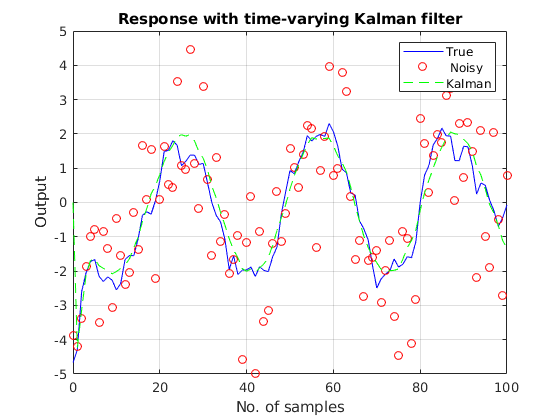

figure
plot(t, Y, 'b', t, Yn, 'or', t, Yk, 'g--'),
xlabel('No. of samples'), ylabel('Output')
title('Response with time-varying Kalman filter')
legend('True', ' Noisy', 'Kalman')
grid on

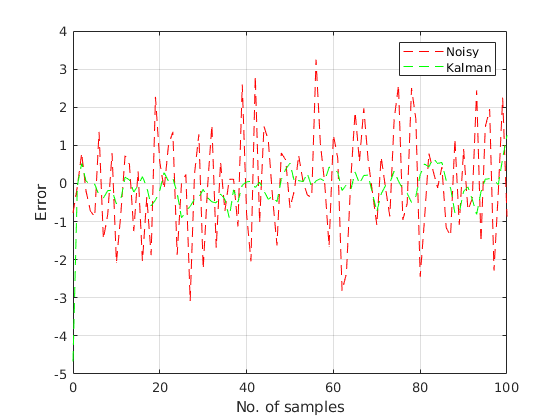


figure
plot(t, Y-Yn,'r--', t, Y-Yk','g--'),
xlabel('No. of samples'), ylabel('Error')
legend('Noisy', 'Kalman')
grid on

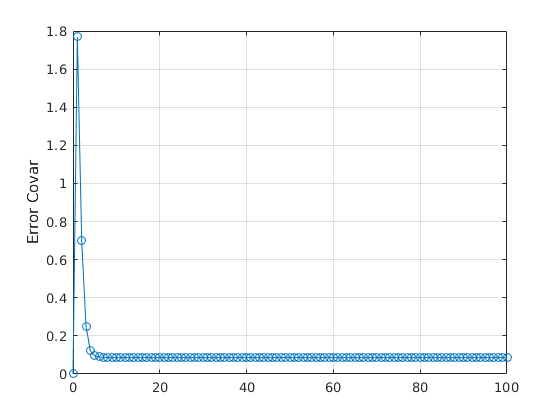

% The time varying filter also estimates the output covariance during the 
% estimation. Plot the output covariance to see if the filter has reached steady 
% state (as we would expect with stationary input noise):

figure
plot(t, Py, '-o' ), ylabel('Error Covar'),
grid on

From the covariance plot you can see that the output covariance did reach a steady state in about 5 samples. From then on, the time varying filter has the same performance as the steady state version.

Compare covariance errors:

diff_n = Y-Yn;
diff_k = Y-Yk';
% Root mean squarred error
rmse_n = sum(diff_n.*diff_n)/length(diff_n);
rmse_k = sum(diff_k.*diff_k)/length(diff_k);

% RMSE before filtering (measurement error):

rmse_n

rmse_n = 1.8676

 
% RMSE after filtering (estimation error):

rmse_k

rmse_k = 0.3619

## Kalman gain matrix

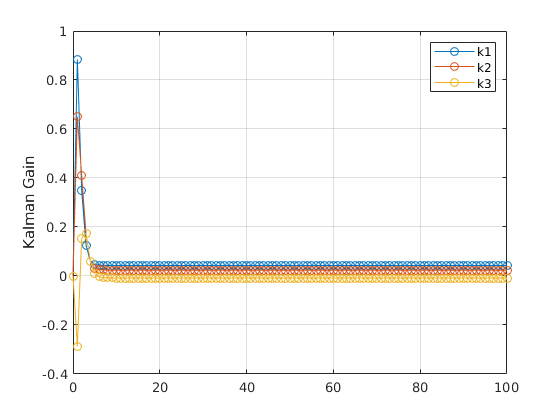

figure
plot(t, Ke, '-o'), ylabel('Kalman Gain'),
legend('k1', 'k2', 'k3')
grid on